# Compensación en Adelanto LGR

Autor(a): Luis Tomás García Andrade, Instituto Tecnológico de Tuxtla Gutiérrez, Departamento de Ingeniería Eléctrica y Electrónica

## Resumen

Los estudiantes diseñarán un compensador en adelanto utilizando el LGR (método de la bisectriz) y con la ayuda de Matlab graficarán la respuesta del sistema antes y después del compensador diseñado.

## Objetivos de Aprendizaje

El objetivo principal de la actividad es evaluar el desempeño del compensador en adelanto diseñado utilizando el Lugar Geométrico de las Raíces con el método de la bisectriz.

Para poder hacer la evaluación se deben realizar las gráficas de las respuestas al escalón y a la rampa del sistema sin compensar y compensado con los datos de los valores deseados y los obtenidos del diseño del compensador.

Las gráficas se deberán presentar en dos figuras una para la respuesta al escalón y la otra con la respuesta a la rampa, en cada figura deberán estar representadas el sistema compensado y sin compensar para hacer la evaluación del desempeño del compensador más accesible.

Con los datos obtenidos de las gráficas determinar si el compensador diseñado cumple con las especificaciones de desempeño.

## Antes de empezar 

Este cuaderno computacional en MATLAB, o Live Script está diseñado para usarse con el código visible y mostrando los resultados en el cuaderno. En la pestaña **View** de las opciones de MATLAB (Toolstrip), en la sección **View**, seleccione **Output Inline**. De forma alternativa, seleccione **Output inline **usando el ícono   en la esquina derecha del editor del Live Script. 

 Interactuar con este Live Script le permitirá familiarizarse con MATLAB a medida que se introducen conceptos y comandos juntos. Si necesita más entrenamiento, considere realizar el curso [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), un tutorial en línea de 2 horas que enseña los conceptos básicos de MATLAB. 

   Para una experiencia óptima, siga las instrucciones y pasos en la secuencia indicada. Pase a una nueva sección sólo después de completar la anterior. Algunas secciones dependen de variables creadas en secciones anteriores y generarán errores si se ejecutan en desorden.

En este cuaderno tendrá la oportunidad de explorar la visualización de conceptos introducidos, pero también podrá usar ejercicios que le permitirán interactuar con el código y desafiar su comprensión de esos conceptos y su profesor puede usarlas para calificar y verificar la finalización.

## Sección 1: Conceptos 

Considere el sistema de control de posición de la siguiente figura [1].

  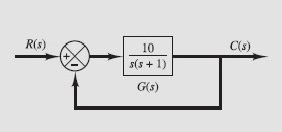

 La función de transferencia del camino directo es:

  G(s) = $\frac{10}{s\left(s+1\right)}$

La función de transferencia en lazo cerrado para el sistema es:

$\frac{C\left(s\right)}{R\left(s\right)}$ = $\frac{10}{s^2 +s+10}$

Se desea diseñar un compensador de adelanto Gc(s) tal como se muestra en la figura siguiente de forma que los polos en lazo cerrado dominantes tengan el factor de amortiguamiento 0.5 y la frecuencia natural no amortiguada *ω*n = 3 rad/seg.

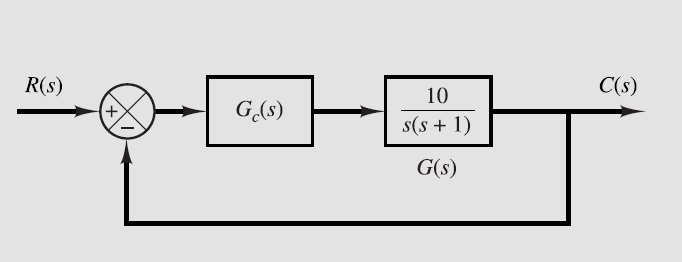

El primer paso para el diseño de compensadores es obtener la gráfica del lugar geometrico de las raíces, para comprobar si ajustando la ganancia se pueden obtener el desempeño deseado.

Funcion de transferencia del sistema en lazo abierto

s=tf('s');
G=10/(s*(s+1));

Función de transferencia de lazo cerrado

Glc=feedback(G,1);

## Sección 2: Obtención de la gráfica del lugar geométrico de las raíces del sistema de lazo abierto y lazo cerrado

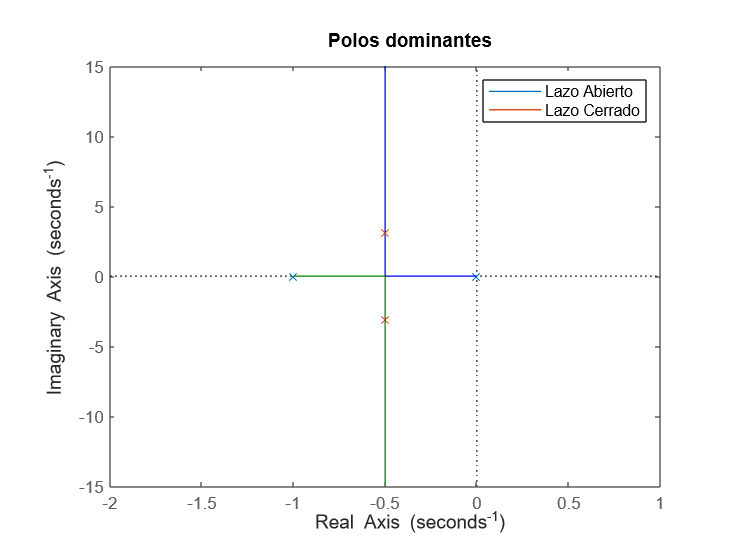

rlocus (G);
hold on
rlocus (Glc);
legend ('Lazo Abierto','Lazo Cerrado');
title('Polos dominantes');
hold off

Se observa que variando la ganancia no se puede cumplir con las especificaciones de desempeño por lo que es necesario el diseño del compensador en adelanto.

El siguiente paso es la construcción de la función de transferencia del polinomio deseado para la obtención de los polos deseados con los datos proporcionados.

$s^2 \;$+ 2$\zeta \omega n$ + $\omega n^2$= $s^2$ + 3$s$ + 9

por lo que la función de transferencia del polinomio deseado es:

Gd=3/(s^2+3*s+9);

## Sección 3: Obtención de la gráfica del lugar geométrico de las raíces del polinomio deseado y de lazo abierto

A partir de esta función de transferencia se grafican el LGR de la misma para la obtención del polo deseado así como las raíces de lazo abierto del sistema sin compensar.

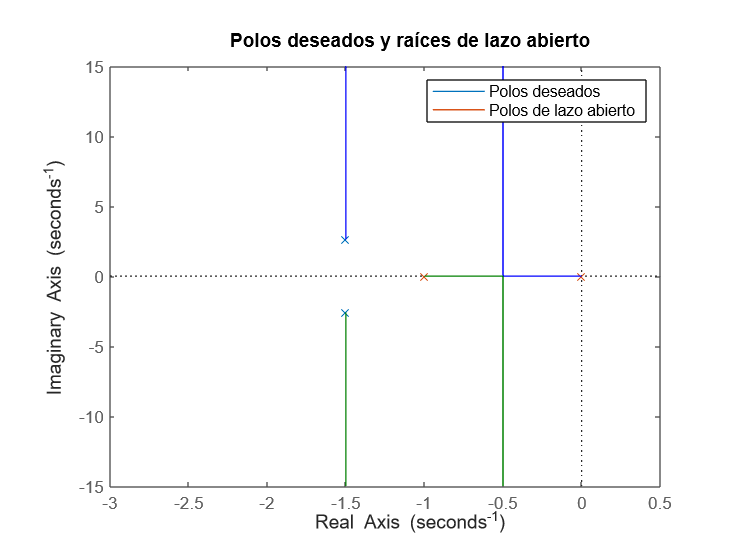

rlocus(Gd);
hold on
rlocus (G);
legend ('Polos deseados','Polos de lazo abierto');
title('Polos deseados y raíces de lazo abierto');
hold off

## Sección 4: Obtención de la función de transferencia del compensador con el método de la bisectriz

Estas gráficas obtenidas sirven para el cálculo de la deficiencia de ángulo así como del cero, el polo y la ganancia del compensador en adelanto haciendo uso de el método de la bisectriz.

Función de transferencia del compensador:

Gc1=((s+1.9432)/(s+4.6458));

Ganancia del compensador en adelanto:

K = 1.2287;

Función de transferencia del compensador en adelanto:

Gc=K*((s+1.9432)/(s+4.6458));

Con el compensador diseñado el siguiente paso es compensar el sistema:

Ga=G*Gc;

## Sección 5: Respuesta al escalón y a la rampa de los sistemas sin compensar y compensado

Por último se obtienen las gráficas de la respuesta al escalón y a la rampa del sistema sin compensar y compensado para poder realizar el análisis y determinar si cumple con las especificaciones proporcionadas.

Gráfica de la respuesta al escalón del sistema sin compensar y compensado:

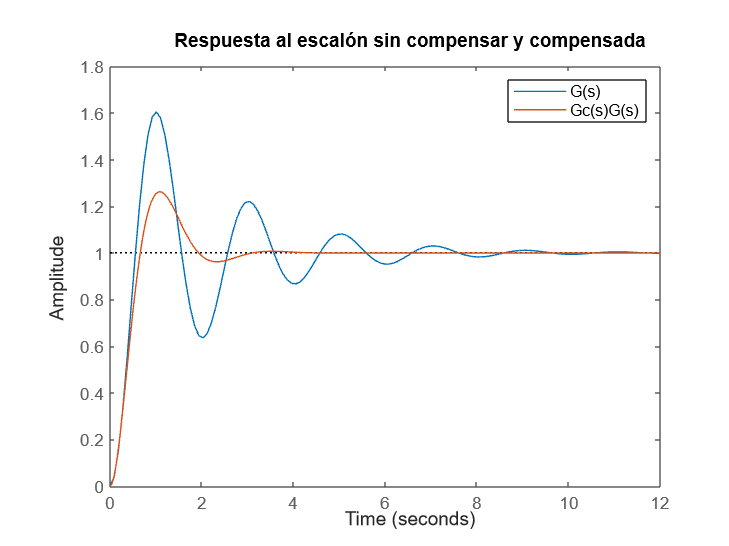

G=feedback(G,1);
step (G);
title('Respuesta al escalón sin compensar y compensada')
hold on
Ga=feedback(Ga,1);
step(Ga);
legend ('G(s)','Gc(s)G(s)');
hold off

Gráfica de la respuesta a la rampa del sistema sin compensar y compensado:

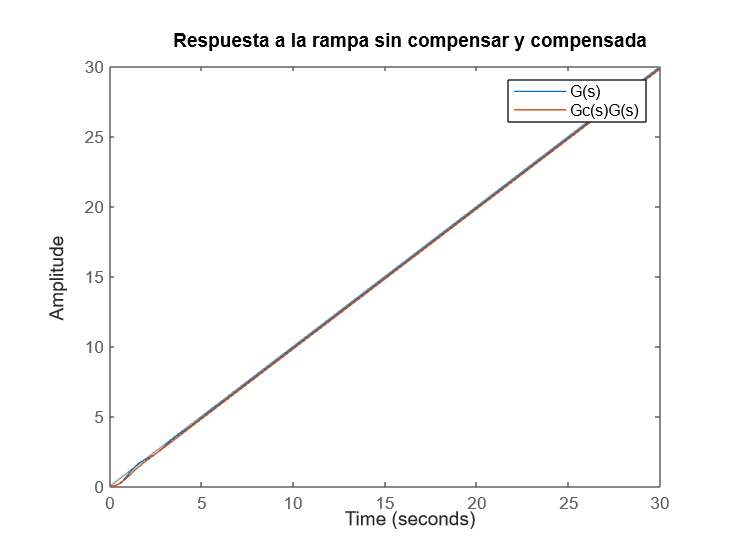

t=0:0.1:30;
x=t;
lsim(G,x,t);
hold on
lsim(Ga,x,t);
legend ('G(s)','Gc(s)G(s)')
title('Respuesta a la rampa sin compensar y compensada')
hold off

Si el compensador diseñado no cumple con las especificaciones hay que repetir el procedimiento ajustando el cero y el polo del compensador hasta cumplir con las especificaciones.

## Recursos Adicionales

Gráfica del lugar de las raíces del sistema dinámico

[https://la.mathworks.com/help/control/ref/tf.rlocus.html](https://la.mathworks.com/help/control/ref/tf.rlocus.html)

Gráfica de respuesta al escalón del sistema dinámico; datos de respuesta al escalón

[https://la.mathworks.com/help/control/ref/dynamicsystem.step.html](https://la.mathworks.com/help/control/ref/dynamicsystem.step.html)

Representar una respuesta en el tiempo simulada de un sistema dinámico para entradas arbitrarias; datos de respuesta simulada

[https://la.mathworks.com/help/control/ref/lti.lsim.html?s_tid=doc_ta](https://la.mathworks.com/help/control/ref/lti.lsim.html?s_tid=doc_ta)

## Referencias 

1.- Ogata, K. (2010). Ingeniería de control moderna. Compensación en adelanto, 313-317